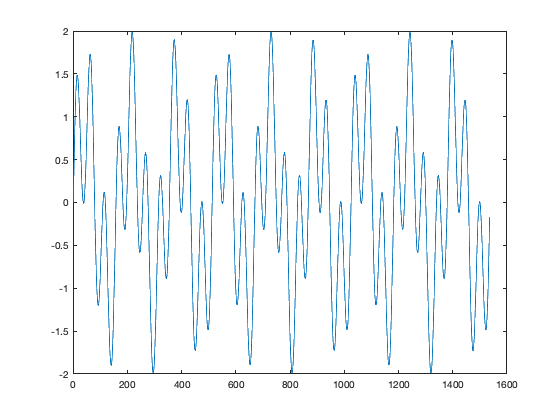

fs = 512;                    % Sampling frequency (samples per second)
dt = 1/fs;                   % seconds per sample
StopTime = 3;             % seconds
t = (0:dt:StopTime-dt)';     % seconds
num_samples = length(fs*t); 
sd = 0.2; 
noise = sd*randn(1, num_samples); 
F1 = 3;         
F2 = 10; % Sine wave frequency (hertz)
data = sin(2*pi*F1*t) + sin(2*pi*F2*t); 

plot(data)


%% repeat 

real_data = repmat(data,1,5); 
tmp = repmat(real_data,1,1,3); 
plot(squeeze(tmp(:,1,1)))

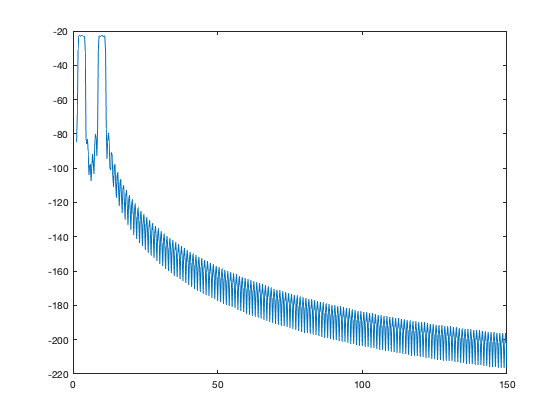


data_for_S = permute(tmp,[2,3,1]); 
%% 
params.Fs = 512;
params.fpass = [1 150];
params.err = [1 0.05];
params.trialave = 0;
params.tapers = [4 7]; 
num_ch = 3; 
num_trials = 5; 

% data is trial x ch x time 
% data permuted to time x trial x ch 

for i=1:num_ch
    for j = 1:num_trials 
        [S(j,i,:),f,Serr(:,:,i)] = mtspectrumc(squeeze(permute(data_for_S(j,i,:),...
             [3,1,2])),params);
    end 
end 

%% 
pow_prestim = 10*log(S);


%% plot PSD 

plot(f,squeeze(pow_prestim(1,1,:)),'LineWidth',0.75)